# Environment MPPT Creation

## Set up de Environment

Speedup Options

useFastRestart = true;
useGPU = true;
useParallel = false;
USE_PRE_TRAINED_MODEL = true; % Set to true, to use pre-trained model
oldAgentName = "agent_6000.mat"; % Specify the pre-trained model

Observation info

numObs = 4;
observationInfo = rlNumericSpec([numObs 1]);
observationInfo.Name = 'observation';

Create the action information

actionInfo = rlFiniteSetSpec([-0.03 -0.01 -0.005 -0.001 0 0.001 0.005 0.01 0.03]); %
actioInfo.Name = 'action';

Environment Information

mdl = 'rlMpptModel'; %% environment
open_system(mdl);
load_system(mdl);
blk = [mdl, '/RL Agent']; % name of agent block
env = rlSimulinkEnv(mdl, blk, observationInfo, actionInfo);
env.ResetFcn = @(in) localResetFcn(in, mdl);

## Create Networks

RL parameters

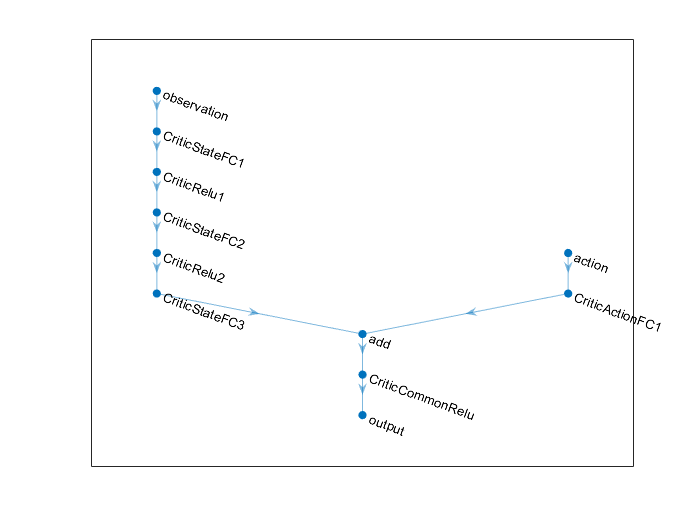

%RL parameters
Ts = 0.01; % Agent sample time
Tf = 0.5;    % Simulation end time
createDQNNetworks; %creating the critic network
figure
plot(criticNetwork)

device = "gpu";
criticOptions = rlRepresentationOptions('Optimizer','adam','LearnRate',0.0001, 'UseDevice', device);
obsInfo = getObservationInfo(env);
actInfo = getActionInfo(env);
critic = rlQValueRepresentation(criticNetwork,obsInfo,actInfo,...
    'Observation',{'observation'},'Action',{'action'},criticOptions);

%% DDPG Agent Options
agentOptions = rlDQNAgentOptions;
agentOpts.ResetExperienceBufferBeforeTraining = not(USE_PRE_TRAINED_MODEL);
agentOptions.SampleTime = Ts;
agentOptions.DiscountFactor = 0.9;
agentOptions.MiniBatchSize = 512;
agentOptions.ExperienceBufferLength = 1e6;
agentOptions.EpsilonGreedyExploration.Epsilon = 1;
agentOptions.EpsilonGreedyExploration.EpsilonMin = 0.001;
agentOptions.EpsilonGreedyExploration.EpsilonDecay = 0.0001;
agentOptions.UseDoubleDQN = true;
if USE_PRE_TRAINED_MODEL
    curDir = pwd;
    saveDir = 'savedAgents';
    cd(saveDir);
    load(oldAgentName, 'agentObj');
    cd(curDir);
else
    agentObj = rlDQNAgent(critic,agentOptions);
end

## Training Options

trainingOptions = rlTrainingOptions;
trainingOptions.MaxEpisodes = 1000;
trainingOptions.MaxStepsPerEpisode = round(Tf/Ts);
trainingOptions.ScoreAveragingWindowLength = 56; % the number of episodes included in an average
trainingOptions.StopTrainingCriteria = 'AverageReward';
trainingOptions.StopTrainingValue = 10000;
trainingOptions.SaveAgentCriteria = 'EpisodeReward';
trainingOptions.SaveAgentValue = 150;
trainingOptions.SaveAgentDirectory = pwd + "savedAgents";
trainingOptions.Plots = 'training-progress';
trainingOptions.Verbose = false;
trainingOptions.UseParallel = useParallel;
if useParallel
    trainingOptions.Parallelization = 'async';
    trainingOptions.ParallelizationOptions.StepsUntilDataIsSent = 32;
end

trainingResults = train(agentObj,env,trainingOptions);

## Save Results

%% SAVE AGENT
%reset(agentObj); % Clears the experiencbuffer
curDir = pwd;
saveDir = 'savedAgents';
cd(saveDir)
save('agent_10000','agentObj');
save('trainingResults_10000','trainingResults');
cd(curDir)